clear 
clc
close all
all_units = [];
all_units_stats = [];

cd /media/ben/'Extreme SSD'/analysisData/aluminumAudio/ % optional 
[file,path] = uigetfile('*.mat');
cd(path)
load(file)


all_units = [all_units;all_psth.United]

all_units_stats = [all_units_stats;all_psth.stats]

timeVec = all_psth.time_vector;

save('allUnitsAud.mat',"all_units_stats","all_units",'timeVec')

allUnitsNorm = normalize(all_units,2,'zscore')

allUnitsNorm =     0.7751    0.7751   -0.9222   -0.3564    0.7751   -0.9222   -0.3564    0.7751   -0.3564   -0.3564    0.2093    0.2093    3.6038    0.7751    0.2093   -0.9222   -1.4879   -0.3564   -0.3564    1.3408   -0.9222    0.2093    1.3408   -0.3564    0.2093    1.9066   -0.9222   -0.3564    0.2093   -0.3564    1.9066    1.3408   -0.9222   -0.9222   -0.3564    2.4723    0.7751   -0.9222   -0.9222   -0.3564   -0.3564   -0.3564   -0.3564    1.3408    0.7751    0.7751    0.7751    1.9066   -0.3564   -0.3564
   -1.0279    0.4547    0.9489   -1.5221   -0.0395   -1.0279   -0.5337   -0.0395   -0.5337   -0.0395    1.9372   -1.0279    0.4547   -0.0395    0.9489   -0.0395   -0.5337   -1.0279   -0.5337   -0.5337   -0.0395    1.4430    1.9372    0.9489   -1.0279    0.4547    0.4547    1.9372   -0.0395    1.9372   -1.5221   -1.5221   -0.0395   -0.0395   -0.0395    0.9489   -1.5221   -1.0279    1.9372    0.4547    1.9372    1.9372   -0.5337    1.4430   -0.0395   -0.5337   -0.0395   -0.0395   -

% allUnitsNorm = all_units - mean(all_units,2)

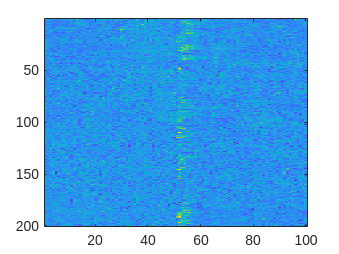

imagesc(allUnitsNorm)

 [M,I] = max(allUnitsNorm(:,50:55)')

M =     0.2093    2.9256    4.2060    2.3421    3.6820    1.2618    2.4422    1.0928    0.2542    1.2939    2.2337    3.1269    1.7753    2.8245    4.4171    2.4252    0.9715    2.5920    2.0805    2.5315    1.4509    3.8195    1.0399    0.6963    1.9191    4.3624    2.8671    5.5971    3.9618    3.7488    5.4207    2.3233    0.9160    1.6059    0.2539    3.1260    2.0513    2.8112    4.4501    3.8483    0.2743    0.0407    1.3278    0.1773    1.3204    0.4658    1.3000    6.9840    2.8167    0.7490


I =      6     4     5     6     6     4     6     4     5     6     6     6     4     4     6     2     5     3     3     5     2     2     3     3     4     6     6     4     5     5     4     5     4     3     1     5     5     5     5     5     5     3     3     2     6     2     1     3     3     3


I = I + 49

I =     55    53    54    55    55    53    55    53    54    55    55    55    53    53    55    51    54    52    52    54    51    51    52    52    53    55    55    53    54    54    53    54    53    52    50    54    54    54    54    54    54    52    52    51    55    51    50    52    52    52


[V,ind] = sort(M,'descend')

V =     8.0597    7.2406    6.9840    6.5587    6.2915    5.5971    5.4207    5.2752    5.1822    4.8310    4.7826    4.7574    4.5962    4.4726    4.4501    4.4171    4.3624    4.2060    4.1826    4.1089    4.0058    3.9618    3.9045    3.8893    3.8483    3.8195    3.8171    3.7488    3.6887    3.6820    3.6254    3.6197    3.5548    3.4915    3.1884    3.1881    3.1608    3.1368    3.1269    3.1260    3.1172    3.0903    3.0807    3.0500    3.0490    3.0322    3.0195    2.9444    2.9433    2.9406


ind =    110   146    48   191   197    28    31   185    81   192   115   106   136   189    39    15    26     3    76   144   190    29   154   152    40    22   187    30    99     5   195   177   113   188   200   114   196   140    12    36   125   193    79    72    95    90   198   138    96    98


allU = allUnitsNorm(ind',:)

allU =    -0.6339    0.2835   -0.3281    0.2835    0.7641   -0.5902    0.4583   -0.1970    0.0651   -0.0223   -0.1970   -0.3718    0.0214   -0.0660    0.3709    0.1088    0.5893   -0.8960   -1.8134    0.5020   -0.0660   -0.6776    0.8078    0.7204   -0.4155    0.1088    0.0214   -0.6339   -0.5465    0.3709   -1.0271   -0.4155   -0.8960   -0.1970    0.0214   -0.7650    0.1962    0.6767    0.5020    0.0651   -0.5465    0.4146   -0.4155   -0.5028   -0.1533   -0.2844   -0.4591   -0.2407   -0.2844   -1.3766
   -1.0163    0.1864   -0.1143   -0.6462    0.2558   -0.7156   -0.2068    0.4640    0.5102   -0.4149    0.0476    0.8109    0.5102   -0.6000   -0.1836    0.3483    0.3252   -0.4149   -0.2299    0.3021    0.5565   -0.2530    0.3946    0.3483   -0.1143   -0.6231   -0.4843   -0.2762    0.3483    0.3946   -0.3224   -0.4149   -0.2993    0.6027   -0.1143   -0.3918    0.8803    0.4408   -0.1836    0.9034   -0.6000   -0.4381    0.6027    0.2327   -0.6925   -0.2299   -0.1374    0.2327   -0.0680  

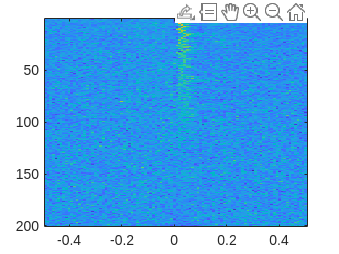

imagesc(timeVec,[1:200],allU)
colormap('default')